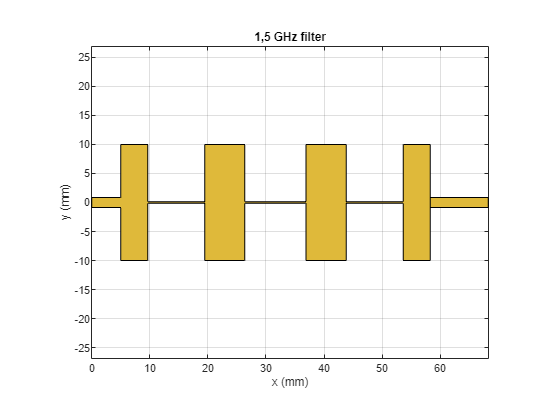

clc
clear all
close all
format longg

points = 200;

met = metal('copper');
met.Thickness = 18e-06; % 1/2 oz copper (18um)
sub = dielectric("RO4350B");
sub.Thickness = 0.76e-3;

wdt = [1.700 20 0.275] * 1e-3;
% wdtalt = [1.700 8.48 0.290] * 1e-3;
wdtalt2 = [1.700 7.858 0.290] * 1e-3;
% wdtalt3 = [1.700 6.400 0.7084] * 1e-3;

pg_filtlow = [5 4.634 9.827 6.909 10.54 6.909 9.827 4.634 10] * 1e-3; % 1.5
% filthig = [5 1.390 2.948 2.073 3.163 2.073 2.948 1.390 5] * 1e-3; % 5
% filthig2 = [5 0.8688 1.843 1.296 1.977 1.296 1.843 0.8688 5] * 1e-3; % 8
% filthig3 = [5 0.8806 1.874 1.320 2.037 1.353 2.062 1.359 2.062 1.353 2.037 1.320 1.874 0.8806 5] * 1e-3; % 8 13red
% filthig4 = [5e3 434.4 921.3 647.8 988.3 647.8 921.3 434.4 5e3] * 1e-6; % 16
% filthig5 = [5e3 434.4 921.3 647.8 988.3 647.8 921.3 434.4 5e3] * 1e-6; % 5, 13red, butter
% filthig6alt = [5 2.420 2.676 3.988 2.860 4.102 2.860 3.988 2.676 2.420 5] * 1e-3; % 9 red, alt impedance 5500
% filthig7alt = [5 2.438 2.697 4.030 2.892 4.178 2.929 4.203 2.929 4.178 2.892 4.030 2.697 2.43 5] * 1e-3; % 13 red, alt impedance, 5500
% filthig8alt2 = [5 2.402 2.410 4.024 2.562 4.182 2.592 4.209 2.592 4.182 2.562 4.024 2.410 2.402 5] * 1e-3; % 13 red, alt impedance 6000
pg_filthig9alt2 = [10 2.059 2.066 3.449 2.196 3.584 2.221 3.607 2.221 3.584 2.196 3.449 2.066 2.059 5] * 1e-3; % 13 red, alt impedance 8000
% filthig10alt2 = [5 2.520 1.855 4.503 1.875 4.766 1.879 4.827 1.880 4.827 1.879 4.766 1.875 4.503 1.855 2.520 5] * 1e-3; % 15 red, alt impedance 7000
% filthig10alt3 = [5 2.367 3.158 3.879 3.344 4.041 3.389 4.078 3.399 4.078 3.389 4.041 3.344 3.879 3.158 2.367 5] * 1e-3; % 15 red, alt impedance (19, 80) 6500

[filterl, pcbl, lengthsl, widthsl, L_totl, W_totl] = widths_to_filt(pg_filtlow, wdt, met, sub);
[filterh, pcbh, lengthsh, widthsh, L_toth, W_toth] = widths_to_filt(pg_filthig9alt2, wdtalt2, met, sub);
[filter_sum, pcb_sum, L_tot, W_tot] = join_filters(filterl, L_totl, W_totl, filterh, L_toth, W_toth, wdt, met, sub);

figure
subplot(1, 2, 1)
show(filterl)
title("1,5 GHz filter")

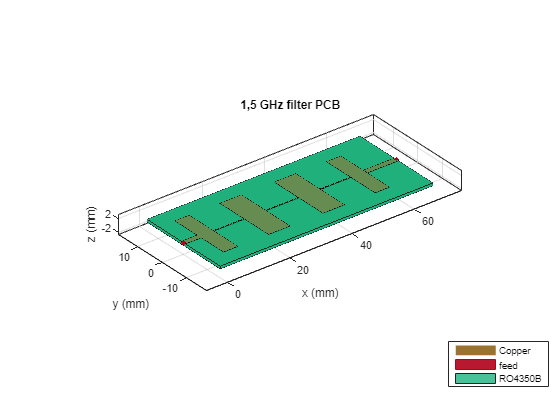

subplot(1, 2, 2)
show(pcbl)
title("1,5 GHz filter PCB")

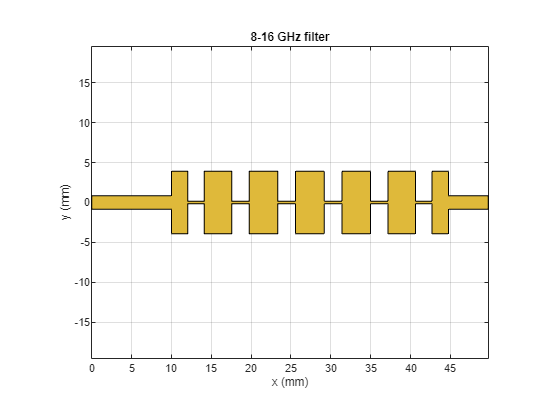


figure
subplot(1, 2, 1)
show(filterh);
title("8-16 GHz filter")

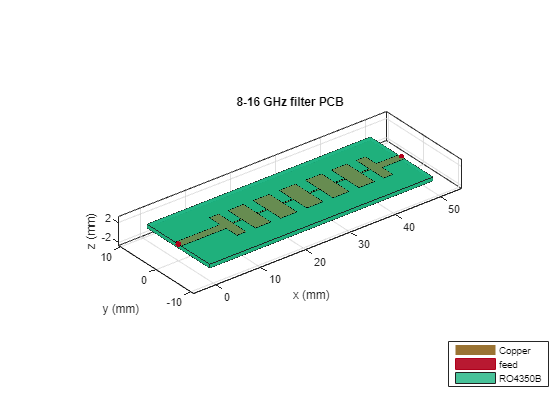

subplot(1, 2, 2)
show(pcbh);
title("8-16 GHz filter PCB")

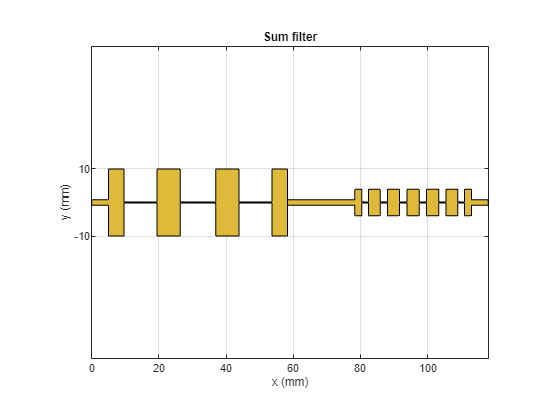


figure
subplot(1, 2, 1)
show(filter_sum);
title("Sum filter")

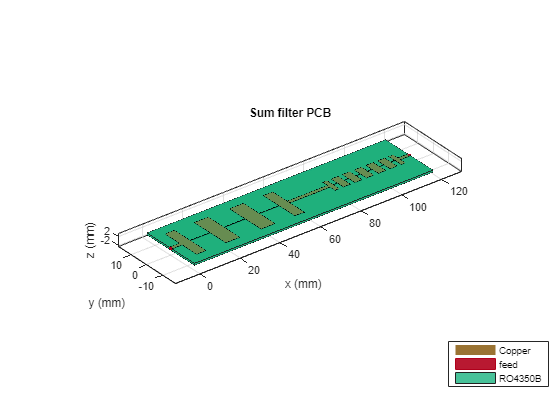

subplot(1, 2, 2)
show(pcb_sum);
title("Sum filter PCB")

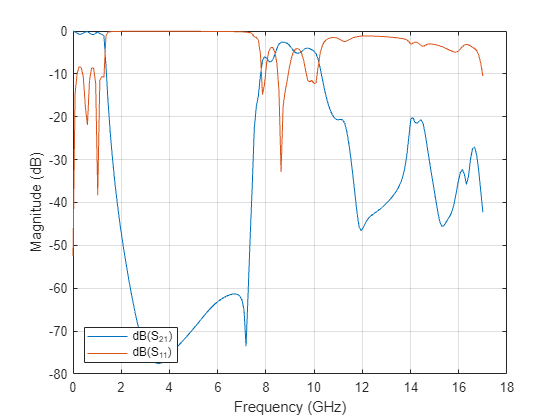


sparl = sparameters(pcbl,linspace(1e6,17e9,points));
figure;
rfplot(sparl,[2 1], 1);
legend(Location="southwest")

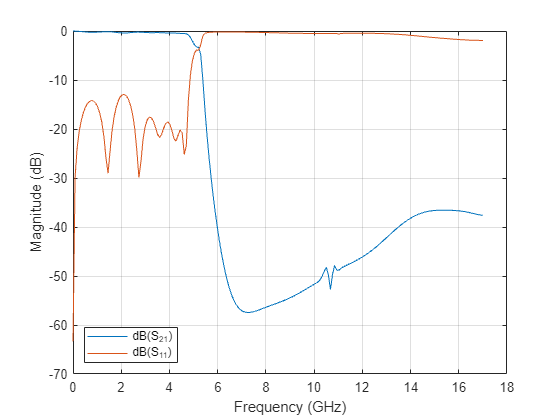

rfwrite(sparl,'test3/iter2/filt_pg_low_2.s2p')

sparh = sparameters(pcbh,linspace(1e6,17e9,points));
figure;
rfplot(sparh,[2 1], 1);
legend(Location="southwest")

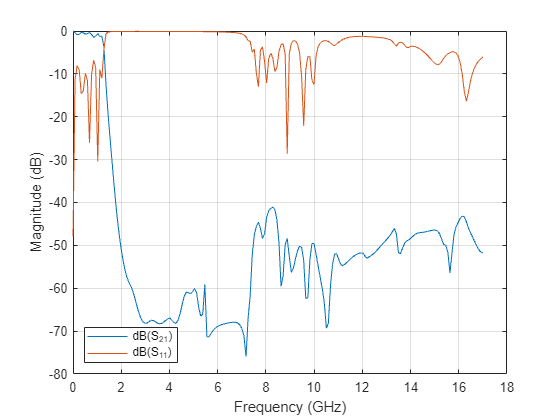

rfwrite(sparh,'test3/iter2/filt_pg_hi.s2p')

sparfull = sparameters(pcb_sum,linspace(1e6,17e9,points));
figure;
rfplot(sparfull,[2 1], 1);
legend(Location="southwest")

rfwrite(sparfull,'test3/iter2/filt_pg_full.s2p')